# Problem 2

Let us consider the triangles $T_{1} = 215$ and $T_{2} =216$ of the mesh **meshHole**. 

clearvars
close all
format short e

## (a) [2 points]

The $x$**-coordinate** of the barycenter of the triangle $T_{1}$ is, 

$\lozenge$0.415886

$\bullet$0.435653

$\bullet$0.445768

$\bullet$Leave it empty (no penalty)

$\bullet$0.425912

eval('meshHole');

vertexsT1 = nodes(elem(215,:),:);
x_barycenter = sum(vertexsT1(:,1))/3;

fprintf(['Part A\n',...
    'The x-coordinate of the barycenter of the triangle T1 is x = %.6f\n'],x_barycenter)

Part A
The x-coordinate of the barycenter of the triangle T1 is x = 0.415886


### **Solution of part (a)**


$$x = 0.415886\triangleright$$


## (b) [2 points]

The $y$**-coordinate** of the point inside the triangle $T_{2}$ with barycentric coordinates $(0.1,0.7,0.2)$ is,

$\lozenge$0.525334

$\bullet$0.555726

$\bullet$0.535512

$\bullet$0.545643

$\bullet$Leave it empty (no penalty)

vertexsT2 = nodes(elem(216,:),:)

vertexsT2 =    3.8773e-01   5.0718e-01
   5.2850e-01   5.0146e-01
   4.9399e-01   6.1796e-01


alphas = [0.1,0.7,0.2];
y = alphas*vertexsT2(:,2);
fprintf(['Part B\n',...
    'The y-coordinate of the point inside the triangle T2 with barycentric coordinates alpha = [0.1,0.7,0.2] is y = %.6f'],y)

Part B
The y-coordinate of the point inside the triangle T2 with barycentric coordinates alpha = [0.1,0.7,0.2] is y = 0.525334

### **Solution of part (b)**


$$y = 0.525334\triangleright$$


Since $T_{1}$ and $T_{2}$ share a common edge, let us now consider the quadrilateral obtained by joining the two mentioned triangles and number it appropriately by taking vertex number one of $T_{1}$ as vertex number one of the final quadrilateral. Consider also the point $𝑄=(0.440000,0.545000)$

## (c) [3 points]

The second barycentric coordinate of $Q$ with respect to the quadrilateral is, 

$\bullet$0.267278

$\bullet$0.277341

$\bullet$0.287512

$\bullet$Leave it empty (no penalty)

$\lozenge$0.297403

nods = [elem(215,:);elem(216,:)];
fprintf('Nodes triangle T1:%5d%5d%5d\n',nods(1,:))

Nodes triangle T1:   41   49   58


fprintf('Nodes triangle T2:%5d%5d%5d\n',nods(2,:))

Nodes triangle T2:   49   67   58


*Note at solution: C*learly, the 1st node of the quadrilateral is global node 41, 2nd is global node 49, 3rd node is global node 67, and 4th is global node 58. So global nodes 49 and 58 are the ones in the common edge.

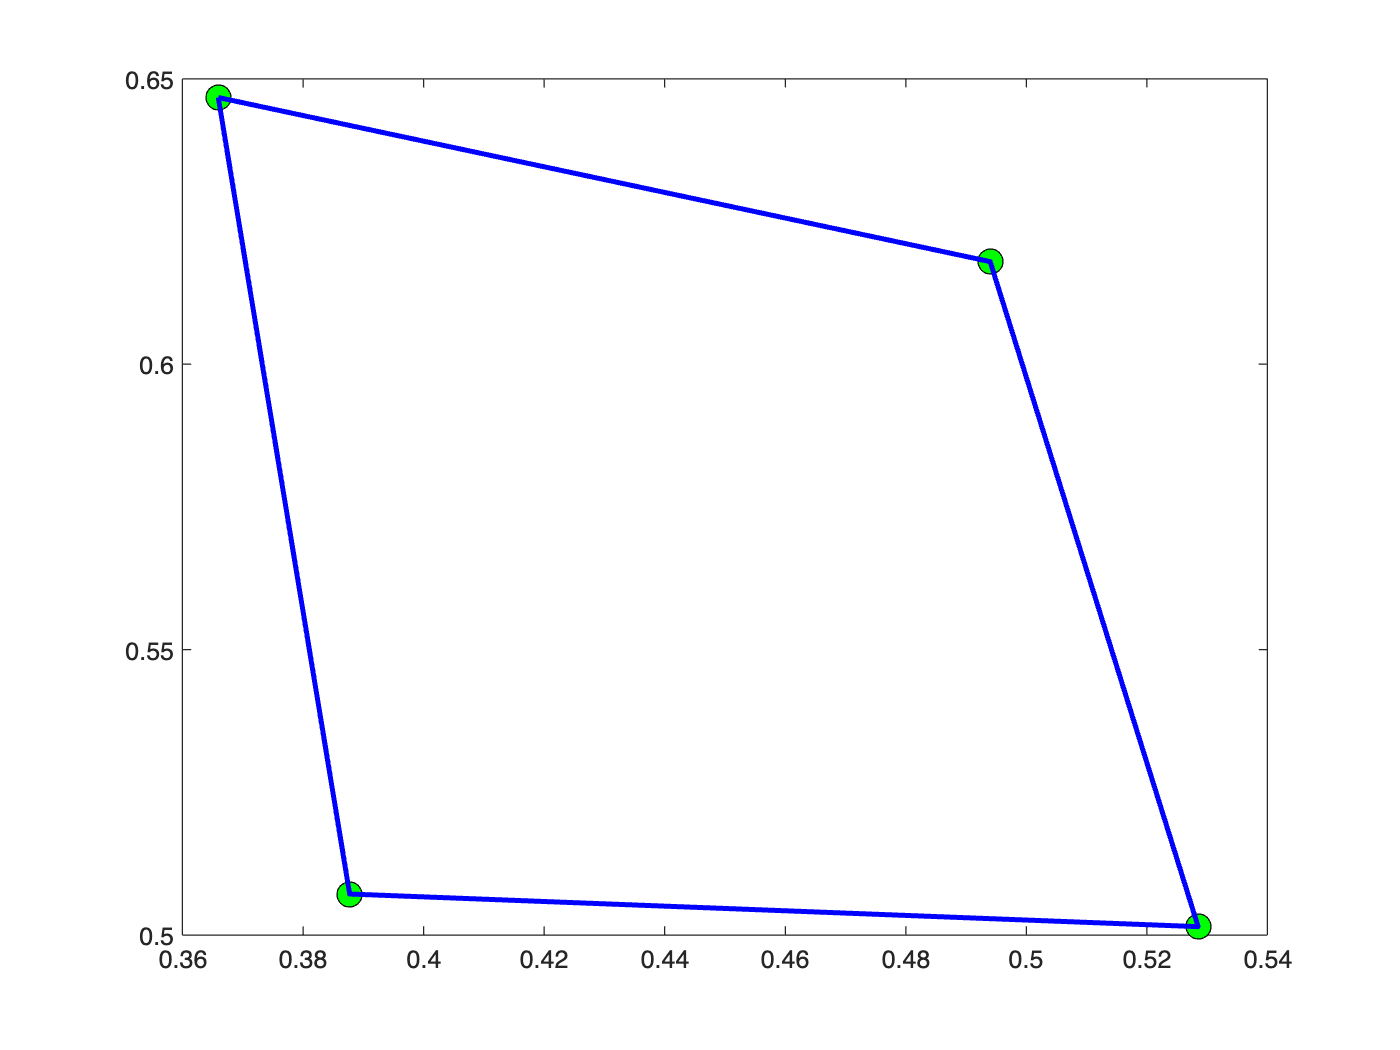

vertexsQuad = [nodes(41,:); ...  % 1st node of the quadrilateral is global node 41
    nodes(49,:); ....            % 2nd node of the quadrilateral is global node 49
    nodes(67,:); ....            % 3rd node of the quadrilateral is global node 67
    nodes(58,:)];                % 4th node of the quadrilateral is global node 58
vertexsQuadPlot = [vertexsQuad; vertexsQuad(1,:)];
plot(vertexsQuad(:,1),vertexsQuad(:,2),...
    'Marker','o',...
    'MarkerFaceColor','green',...
    'MarkerEdgeColor','black',...
    'MarkerSize',10)
hold on
plot(vertexsQuadPlot(:,1),vertexsQuadPlot(:,2),...
    'Color','blue',...
    'LineWidth',2)
hold off

q = [0.44,0.545];
[alphas,isInside] = baryCoordQuad(vertexsQuad,q);
fprintf(['Part C\n',...
    'The third barycentric coordinate of Q wrt the quadrilateral is, alpha(3) = %.6f\n'],alphas(3))

Part C
The third barycentric coordinate of Q wrt the quadrilateral is, alpha(3) = 0.297403


### **Solution of part (c)**


$$\alpha_{3} = 0.297403\triangleright$$


## (d) [3 points]

Consider the function that $f(v_{i}) = x_{i} + \cos(y_{i})$ on the vertexs $v_{i} = (x_{i},y_{i})$, $i=1,2,3,4$. The interpolated value for $f(Q)$ is, 

$\bullet$1.274127

$\bullet$1.266018

$\lozenge$1.293577

$\bullet$1.285327

$\bullet$Leave it empty (no penalty)

f = @(x,y) x + cos(y);
xi = vertexsQuad(:,1); yi = vertexsQuad(:,2);
fi = f(xi,yi);
f_interp = alphas*fi;
fprintf(['Part D\n',...
    'The interpolated value of f(Q) is f_interp(Q) = %.6f\n'],f_interp)

Part D
The interpolated value of f(Q) is f_interp(Q) = 1.293577


### **Soluiton of part (d)**


$$f_{\text{interp}}(Q) = 1.293577\triangleright$$
